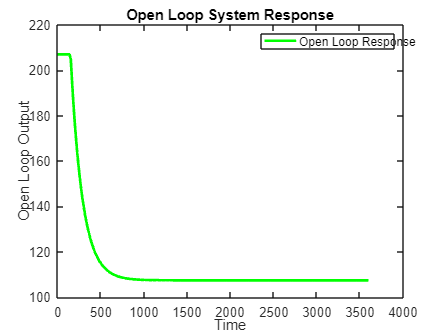

% Define parameters
k = 99.60885347;    % Value of 'k'
tau = 135.9927555;    % Value of 'tau'
td = 147;            % Time delay

% Define control input function (step function with delay)
u = [zeros(td, 1); ones(3600-td, 1)];

% Initial condition
xr = 50;   % Reference value
x0 = 207;  % Initial value of x

% Time span
tspan = 0:15:3600;

% Initialize the output for open loop
x_open = zeros(size(tspan));
x_open(1) = x0;

% Calculate the open-loop response
for i = 2:length(tspan)
    if tspan(i) > td
        x_open(i) = x0 - k * (1 - exp(-(tspan(i) - td) / tau));
    else
        x_open(i) = x0;
    end
end

% Plot the open-loop response
figure;
plot(tspan, x_open, 'g', 'LineWidth', 2);
xlabel('Time');
ylabel('Open Loop Output');
title('Open Loop System Response');
legend('Open Loop Response');

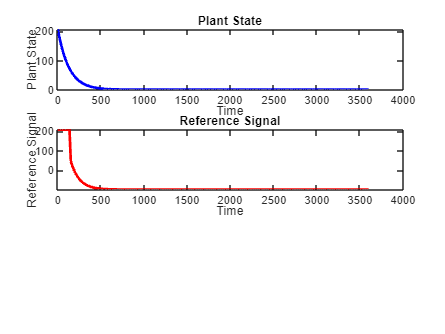

% Define parameters
k = 99.60885347;    % Value of 'k'
tau = 135.9927555;    % Value of 'tau'
td = 147;            % Time delay

% Define control input function (example: step function)
u = [zeros(td, 1); ones(3600-td,1)];

% Initial condition
xr = 50;   % Reference value
x0 = 207;   % Initial value of x

% Define system parameters for MRAC
am = 0.0015; % Reference model parameter
bm = 0.001;  % Reference model parameter
a = 1/tau;   % Plant parameter
b = k/tau;   % Plant parameter
gamma = 1e-06; % Adaptation rate

% Control gains
kx = (am - a)/b
kr = bm/b

% Simulation parameters
dt = 15; % Time step
t_end = 3600; % Simulation time

% Reference signal
t = 0:dt:t_end;
x_hat = 207;
k_m = 150;
tau_m = 100;
r = zeros(size(t));
for i = 1:length(t)
    if t(i) > td
        r(i) = xr - (k_m * (1 - exp(-(t(i) - td) / tau_m)));
    else
        r(i) = x0;
    end
end

% Initialize variables
x = zeros(size(t));  % Plant state
x(1) = x0; % initial condition
theta = zeros(size(t));  % Parameter estimate
theta(1) = 3.5; % initial guess
u = zeros(size(t));  % Control input
error = zeros(size(t));  % Error

% Main loop
for i = 2:length(t)
    % Error
    e = r(i) - x(i-1);
    error(i) = e;
    
    % Control law
    u(i) = kx * x(i-1) + kr * r(i) - theta(i-1) * x(i-1);

    % Limit control input to the range [0, 100]
    u(i) = min(max(u(i), 0), 100);
    
    % Update plant state
    x(i) = x(i-1) + dt * (-a * x(i-1) + b * u(i));
    
    % Adaptation law
    theta_dot = -gamma * e * x(i-1);
    theta(i) = theta(i-1) + dt * theta_dot;
end

% Plot results
figure;
subplot(3,1,1);
plot(t, x, 'b', 'LineWidth', 2);
xlabel('Time');
ylabel('Plant State');
title('Plant State');

subplot(3,1,2);
plot(t, r, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Reference Signal');
title('Reference Signal');

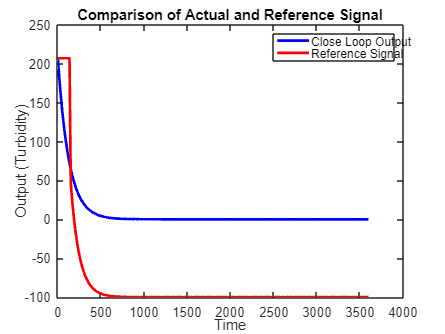


% Comparison plot
figure;
plot(t, x, 'b', t, r, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Output (Turbidity)');
legend('Close Loop Output', 'Reference Signal');
title('Comparison of Actual and Reference Signal');

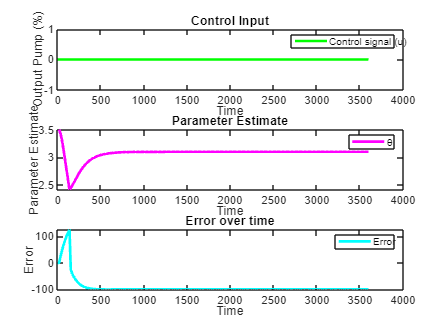


subplot(3,1,1)
plot(t, u, 'g', 'LineWidth', 2);
xlabel('Time');
ylabel('Output Pump (%)');
title('Control Input');
legend('Control signal (u)');

subplot(3,1,2)
plot(t, theta, 'm', 'LineWidth', 2);
xlabel('Time');
ylabel('Parameter Estimate');
title('Parameter Estimate');
legend('θ');

subplot(3,1,3)
plot(t, error, 'c', 'LineWidth', 2);
xlabel('Time');
ylabel('Error');
title('Error over time');
legend('Error');